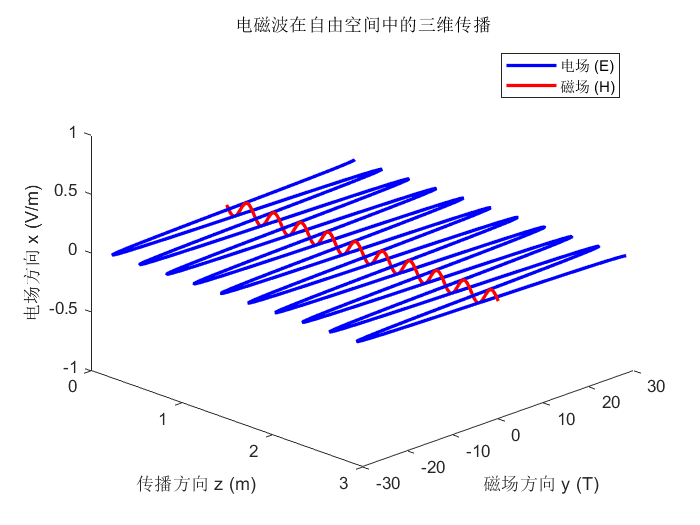

clear all; clc;close all;
%%===================参数设置=====================
%物理常数
c=3e8;%光速m/s
pi=3.1414926;%圆周率
u0=4*pi*1e-7;%真空中的磁导率
e0=1/(36*pi)*1e-9;%真空中的介电质常数
Z0=(u0/e0)^0.5;%真空中的波阻抗

%电磁波参数设置
f=1e9;%电磁波传播的频率Hz
w=2*pi*f;%角频率
lambda=c/f; %波长m
k = 2*pi / lambda;% 波数 (rad/m)
phi=0;%初始相位
EE=20*sqrt(2);%电场振幅
HH=EE/Z0;%磁场振幅

% 空间和时间设置
z = linspace(0, 10*lambda, 500); % 空间范围,沿z方向传播
t = linspace(0, 1/f, 100);       % 时间范围

% 设置三维图形窗口
figure;h = gca;hold on;
% 绘制初始的三维电场和磁场线()
%plot3(x,y,z);这里为了表述清楚，将z轴设置为水平指向右侧
hE = plot3(z, zeros(size(z)), zeros(size(z)), 'b', 'LineWidth', 2); % 电场线 (E场)
hH = plot3(z, zeros(size(z)), zeros(size(z)), 'r', 'LineWidth', 2); % 磁场线 (H场)

% 设置图例、标签、标题和视角
legend('电场 (E)', '磁场 (H)');
xlabel('传播方向 z (m)');
ylabel('磁场方向 y (T)');
zlabel('电场方向 x (V/m)');
title('电磁波在自由空间中的三维传播');
axis([0 max(z) -30 30 -1 1]);

% 设置动态的视角，便于观察三维波传播
view(45, 30);
%%===============建立仿真量=======================
for ti = 1:length(t)
    % 电场随时间和空间的变化 (假设传播方向为z轴正方向)
    E = EE*cos(w*t(ti)-k*z+phi);   % 电场是正弦波，方向假设在x方向
    % 磁场随时间和空间的变化 (磁场与电场正交，传播方向仍为x轴)
    H = HH*cos(w*t(ti)-k*z+phi - pi/2); % 磁场滞后电场90度，方向假设在y方向
    % 更新三维电场图像 (z 对应传播方向，x 对应电场方向)
    set(hE, 'XData', z); % 更新 z 坐标 (传播方向)
    set(hE, 'YData', E); % 更新 x 坐标 (电场)
    set(hE, 'ZData', zeros(size(z))); % 固定 y 轴 (E场在 x 方向)
    
    % 更新三维磁场图像 (z 对应传播方向，y 对应磁场方向)
    set(hH, 'XData', z); % 更新 z 坐标 (传播方向)
    set(hH, 'YData', zeros(size(z))); % 固定 z 轴 (H场在 y 方向)
    set(hH, 'ZData', H); % 更新 y 坐标 (磁场)
    % 实时更新图像
    drawnow; % 更新图像
    pause(0.05); % 控制动画速度  
end